# Matlab Introduction: structures, functions and classes

We've learned about all the Matlab syntax we will need to know about for the remainder of this unit. This final part of the introduction is all about how we organise our data and code to make it easy to revisit and reuse.

## Structures

So far all the variables we've created have ended up stored inside the Matlab Workspace. Remember this is true regardless of whether we've been writing code in any of the following places:

- The Matlab Command Window

- A Matlab script

- A Matlab live script

One problem with endlessly adding variables into the Workspace is that as we start to work on more complicated problems it can get pretty cluttered. It can even become difficult to think of new variable names to avoid overwriting existing ones.

Tip: you can clear all the variables in your workpace with the following command:

clear all;

Structures offer a simple first step to addressing this problem. A structure groups together related variables into containers called fields. The names of fields inside one structure won't clash with the names of fields inside another structure, or with the names of variables sitting directly inside the Workspace. If you have a number of variables related by a common concept, then a structure is a great way to collect those variables together into a single "place".

For example, on this unit we will build different kinds of machine learning classifiers, and each classifier will have various different bits of data associated with it (e.g., training examples, training labels, training parameters). Structures are a good way to bring all the data for a single classifier together. Have a look at the following example:

% read some data from a spreadsheet:
t = readtable('wisc_bc_data.csv');

% store the diagnosis labels inside our structure:
mystruct.labels = categorical(t{:,'diagnosis'});
% delete the labels from the table data:
t(:,'diagnosis') = [];
% store the examples inside our structure:
mystruct.examples = t;
% store some training parameters inside our structure:
mystruct.parameters = [10, 2];
% have a look at mystruct:
mystruct

mystruct = struct with fields:
        labels: [569×1 categorical]
      examples: [569×31 table]
    parameters: [10 2]


Notice that after running this code, all we have added to the Workspace is a single variable: `mystruct`. We could create variables with the same names as the structure's fields, and it wouldn't cause any problems, `mystruct` remains unaffected:

labels = 'just a test'

labels = 'just a test'

examples = 'anything...'

examples = 'anything...'

parameters = 'doesn''t matter'

parameters = 'doesn't matter'

mystruct

mystruct = struct with fields:
        labels: [569×1 categorical]
      examples: [569×31 table]
    parameters: [10 2]


We can also create another structure and change the values inside it without having any impact on our original structure:

% store (nonsense) data inside a second structure, as an example:
mystruct2.labels = [1 2 3];
mystruct2.examples = [4 5 6];
mystruct2.parameters = [11, 3];
mystruct2

mystruct2 = struct with fields:
        labels: [1 2 3]
      examples: [4 5 6]
    parameters: [11 3]


mystruct

mystruct = struct with fields:
        labels: [569×1 categorical]
      examples: [569×31 table]
    parameters: [10 2]


Finally, just as with anything else in Matlab, the variables `mystruct` and `mystruct2` are actually (2D) arrays, and we decide to write other elements of the array at any time, *as long as you write the same kind of structure.* That is, it must contain the same fields:

mystruct(1,5) = mystruct2

mystruct = 1×5 struct array with fields:
    labels
    examples
    parameters


And notice Matlab helpfully fills in the 4 elements in between the ones we've written with matching structures containing all empty fields:

mystruct(1,3)

ans = struct with fields:
        labels: []
      examples: []
    parameters: []


And just to demonstrate that we can't mix different types of structure in the same array, let's try doing it:

mynewstruct.different = 7;
try
    mystruct(1,4) = mynewstruct
catch
    fprintf('this would cause an error if we let it\n');
end

this would cause an error if we let it


## Functions

Functions are another great tool when working on larger problems, giving us the ability to divide code up between multiple scripts, and to keep variables out of the Workspace altogether. As you've worked in object-oriented languages in the past, you might be more familiar with the name *method*. Just like a method, a Matlab function can accept inputs (sometimes called arguments) and return outputs. Here's the general shape of a function declaration in Matlab:

`function [y1,...,yN] = myfun(x1,...,xM)`

`    % we have access to local copies of the inputs x1,...,xM`

`    % do stuff...`

`    % at the end, the outputs y1,...,yN will be returned to the caller`

`end`

As the comments suggest:

- Inside the function we have access to any inputs (`x1,...,xM`) that the caller has passed to us (these variables are passed in as copies and so making changes to them won't affect the caller's originals)

- At the end of the function, all of the outputs (`[y1,...,yN]`) will automatically be returned to the caller (we don't have to explicitly return them as in other languages, this happens automatically, we just need to make sure each of the outputs has been defined)

Unlike in other languages, Matlab doesn't insist on us placing functions inside a class. We can write functions inside normal scripts.

Have a look at the part5_function.m file which contains an example function. Providing we're in the same directory as the function, we can call it from the Matlab Command Window, and from other scripts or live scripts also saved in the same directory. Assuming you have downloaded the function into the same directory that you have this live script saved in, you will be able to run it:

output = part5_function(77)

mynum = 77

foo = 'bar'

num1 = 7

num2 = 7.0002

num3 = 14.0002

myarray =      3     7     5     2     1     5     9


myarray =      3     7     5    10     1     5     9


myarray_min = 1

myarray_max = 10

myarray_average = 5.7143

myarray_total = 40

myarray_sorted =      1     3     5     5     7     9    10


myarray_unique =      1     3     5     7     9    10


output = 'bar'

You'll notice that you see the results of the commands executed in the function appearing inside this live script, but if you check the Workspace you'll see that none of the variables created by those commands have appeared (have a look and check).

The variables created by the function are all *local variables*. They only exist while the function is executing and are stored completely separately from the variables in the Matlab Workspace. So it doesn't matter, for example, if you already had a variable called `foo` sitting inside your Workspace. This variable won't be overwritten or affected in any way by the local variable called `foo` in part5_function.

Make sure you can also call the function from the Matlab Command Window, by copying and pasting the code below, and that you can see the results of the commands executed in the function appearing inside the Command Window:

`output = part5_function(77)`

Again, convince yourself that none of variables created by the function have appeared in your Workspace. You might like to compare this against running part2_script, which does all the same things, but will create variables in your Workspace (because it's just a plain script, and not a function). We'll use functions quite a bit on the unit, so if you're not sure about anything then ask for help before continuing.

## Calling functions with multiple outputs

To see an example of a function that returns more than one output let's call Matlab's built-in `sort()` function again:

myarray = [3 7 5 2 1 5 9]

myarray =      3     7     5     2     1     5     9


[sorted, indices] = sort(myarray)

sorted =      1     2     3     5     5     7     9


indices =      5     4     1     3     6     2     7


Note that to get back multiple outputs you must surround them in square brackets, and separate them with commas. Here, the second output stores the index of each sorted value in the original array. Lots of the built-in Matlab functions can return multiple outputs, but will only do so when you ask to have them. If you just set the function call equal to a single value it will only return its first output:

sorted = sort(myarray)

sorted =      1     2     3     5     5     7     9


If you ask for only the first two then it will only return the first two, etc.

Sometimes you only want one of the later outputs, and in this case you can either create "dummy" variables (that you never actually use) to store the other earlier outputs, or you can use "tilde" symbols in your list of output variable names, see the example below:

[~, indices] = sort(myarray)

indices =      5     4     1     3     6     2     7


The tilde symbol (`~`) tells Matlab that you don't need a particular output back, and allows the built-in functions to avoid doing unnecessary calculations and often to return more quickly. 

Task 1:

% use the min() function to store the smallest value 
% in myarray in a variable called smallest
% type your solution on the line below:
smallest = min(myarray)

smallest = 1

Task 2:

% view the help documentation for the min() function
% hint: you can see help documentation by typing 
% help followed by the name of the function
% type your solution on the line below:
help min

 min    Smallest component.
    For vectors, min(X) is the smallest element in X. For matrices,
    min(X) is a row vector containing the minimum element from each
    column. For N-D arrays, min(X) operates along the first
    non-singleton dimension.
 
    [Y,I] = min(X) returns the indices of the minimum values in vector I.
    If the values along the first non-singleton dimension contain more
    than one minimal element, the index of the first one is returned.
 
    min(X,Y) returns an array with the smallest elements taken from X or Y.
    X and Y must have compatible sizes. In the simplest cases, they can be
    the same size or one can be a scalar. Two inputs have compatible sizes
    if, for every dimension, the dimension sizes of the inputs are either
    the same or one of them is 1.
 
    min(X,[],'all') returns the smallest element of X.
 
    [Y,I] = 

Task 3:

% use the min() function to store the smallest value 
% in myarray in a variable called smallest AND the index
% of the smallest value in myarray in a variable called smallest_index
% type your solution on the line below:
smallest = min(myarray)

smallest = 1

smallest_index = indices(smallest)

smallest_index = 5

Task 4:

% use the min() function to store ONLY the index
% of the smallest value in myarray in a variable called smallest_index
% type your solution on the line below:
smallest_index = indices(min(myarray))

smallest_index = 5

## Overloaded functions

Most of Matlab's internal functions are overloaded, meaning they can accept different numbers of inputs. For example, if you have a quick look at the documentation for the `sort()` function, you can see from the first few paragraphs that it's possible to call it with 1, 2, or 3 inputs:

- `b = sort(a)`

- `b = sort(a, dim)`

- `b = sort(a, dim, direction)`

help sort

 sort   Sort in ascending or descending order.
    B = sort(A) sorts in ascending order.
    The sorted output B has the same type and size as A:
    - For vectors, sort(A) sorts the elements of A in ascending order.
    - For matrices, sort(A) sorts each column of A in ascending order.
    - For N-D arrays, sort(A) sorts along the first non-singleton dimension.
 
    B = sort(A,DIM) also specifies a dimension DIM to sort along.
 
    B = sort(A,DIRECTION) and B = sort(A,DIM,DIRECTION) also specify the
    sort direction. DIRECTION must be:
        'ascend'  - (default) Sorts in ascending order.
        'descend' - Sorts in descending order.
 
    B = sort(A,...,'MissingPlacement',M) also specifies where to place the
    missing elements (NaN/NaT/<undefined>/<missing>) of A. M must be:
        'auto'  - (default) Places missing element

In fact, you can call it with even more inputs and many of the built-in Matlab functions have 10s of different options. In these cases, the function definitions usually aren't written to accept, say, ten different inputs, because this could get annoying. For example, if you only wanted to make use of the first and the 10th option you'd have to put something (even if it was just a "tilde" symbol) for the 8 inputs between... Instead, these functions definitions are written to accept *name-value pair* inputs.

Name-value pair inputs allow you to supply the name of the input you want to set, followed by the value you want it to have. Typically, Matlab functions will take the first few, most commonly used inputs, normally (e.g., `a`, `dim` and `direction` for the `sort()` function) and then any less commonly used inputs as name-value pairs.

For example, the plot() function has lots of extra options for changing the style of the line that is drawn, and these are set using name-value pairs. The following example changes just a few of them to give the idea:

myarray = [3 7 5 2 1 5 9]

myarray =      3     7     5     2     1     5     9


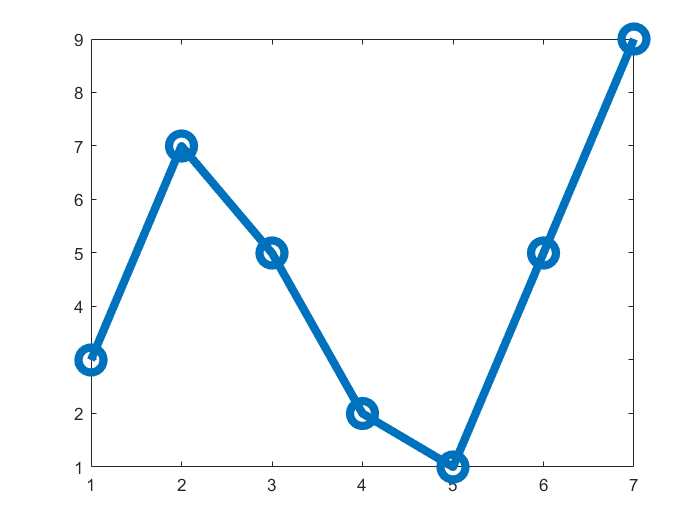

plot(myarray, 'LineWidth', 5, 'Marker', 'o', 'MarkerSize', 15)

More complex Matlab functions often have many optional inputs and we will use name-value pairs fairly regularly in later weeks of the unit.

## Limitations of function declarations

Functions are useful because they give us a separate "space" in which to write code and store variables. But they're so powerful because we can call them from other places (e.g., the Command Window, scripts or live scripts) and get them to do jobs for us. You can even call a function from another function (notice that part`5_function()` is doing this with the built-in functions `min()`, `max()`, `mean()`, etc.) and by writing a few inter-dependent functions (functions that call on each other) you can start to solve really quite complex problems.

There are some limitations regarding where we can define and call functions, however:

- If we want to call a function from other places (Command Window, other scripts, live scripts, other functions) then its declaration must be right at the top of the script, and it must have the same name as the script

- If we only want to call a function from within the script where it is declared, then we can combine the function declaration with normal code, but it must be the last thing in the script (there can't be any code below it)

- The same is true for a live script (this is what prevented me from actually declaring the `myfun()` example up towards the top of this live script - I wanted to put more code below it, which would have generated an error

- We can have multiple function declarations, one below the other, in a script, but it will only be possible to call the very first one (assuming it is right at the top of the file) from other places (Command Window, other scripts, live scripts, other functions) all the others will only be callable by the other functions in the script

The last limitation is a bit disappointing - it would be really nice to tidy away a bunch of useful and related functions into a single file and be able to call them all from anywhere. It would be a bit like tidying a bunch of useful and related variables into a structure. This is something that it would be nice to do as we start to work on more complicated problems and it motivates our only use of classes in Matlab.

## Classes

Matlab allows for a fully object-oriented approach to programming using classes. On this unit we'll make only one specific use of classes, motivated by the limitations on function declarations discussed in the previous section. Here's a summary in words of how we'll use classes, then we'll go on to look at some examples:

- We store related functions together as static methods of an appropriately named class

- Remember static methods are methods you can call without needing to instantiate an object from the class, meaning they can be called with a minimum of fuss

- Our use of classes is about having nicely organised code, with functions that we can call from wherever we want (Command Window, other scripts, live scripts, other functions)

- We're not trying to take a fully object-oriented approach to development with Matlab

Have a look at the static functions declared in the class Part5_class.m and get an idea of what each one does. Here is a brief summary:

- `Part5_class.createModel()` - set up a structure containing model info

- `Part5_class.modelInfo()` - print out summary of model information

- `Part5_class.previewExamples()` - have a look at first 10 rows of the examples table

Now let's use the functions to help us make the structure containing our model, and view some information about it:

% read some data from a spreadsheet:
t = readtable('wisc_bc_data.csv');

% copy out the labels:
labels = categorical(t{1:1:end,'diagnosis'});
% delete the labels from the table data:
t(:,'diagnosis') = [];

% create a model structure:
m = Part5_class.createModel(t, labels, [10, 2]);

model structure created


% see a summary of model information:
Part5_class.modelInfo(m);

model contains:
569 examples
Each with 31 features
And 569 associated labels from 2 classes
Model has 2 parameters


% preview the training examples:
Part5_class.previewExamples(m);

previewing first 10 training examples:


ans = 10×31 table
        id        radius_mean    texture_mean    perimeter_mean    area_mean    smoothness_mean    compactness_mean    concavity_mean    concavePoints_mean    symmetry_mean    fractal_dimension_mean    radius_se    texture_se    perimeter_se    area_se    smoothness_se    compactness_se    concavity_se    concavePoints_se    symmetry_se    fractal_dimension_se    radius_worst    texture_worst    perimeter_worst    area_worst    smoothness_worst    compactness_worst    concavity_worst    concav

% have a look at m:
m

m = struct with fields:
      examples: [569×31 table]
        labels: [569×1 categorical]
    parameters: [10 2]


We'll take exactly this kind of approach in subsequent labs, storing related variables inside a structure (e.g., to define a particular machine learning model) and then passing that structure to various static methods of a helper class in order to do useful things (e.g., classify new examples).

Make sure you're happy with code and how it's working before you move on - it's much better to ask questions now than to be confused in later weeks.

Task 1:

% using the code above for guidance: read the ilpd.cvs file, separate out
% the diagnosis column into a separate categorical array, and use Part5_class
% to build a model called my_m with the parameters [5 1]
% type your solution below:
t2 = readtable('ilpd.csv')

t2 = 583×10 table
    age    tot_bilirubin    direct_bilirubin    tot_proteins    albumin    ag_ratio    sgpt    sgot    alkphos    diagnosis 
    ___    _____________    ________________    ____________    _______    ________    ____    ____    _______    __________

    65          0.7               0.1               187           16          18       6.8     3.3       0.9      'healthy' 
    62         10.9               5.5               699           64         100       7.5     3.2      0.74      'healthy' 
    62          7.3               4.1               490           60          68         7     3.3      0.89      'healthy' 
    58          

cat_diag = categorical(t2{1:1:end, 'diagnosis'});
my_m = Part5_class.createModel(t2, labels, [5, 1]);

model structure created


my_m

my_m = struct with fields:
      examples: [583×10 table]
        labels: [569×1 categorical]
    parameters: [5 1]


Task 2:

% print a summary of the labels stored inside the my_m structure
% type your solution below:
summary(cat_diag)

     diseased      167 
     healthy       416 


Task 3:

% copy the "age" column in the table of examples inside the my_m structure
% into a numerical array called age
% type your solution below:
age = my_m.examples{:, 'age'}

age =     65
    62
    62
    58
    72
    46
    26
    29
    17
    55


Task 4:

% copy the "albumin" column in the table of examples inside the my_m structure
% into a numerical array called albumin
% type your solution below:
albumin = my_m.examples{:,'albumin'}

albumin =     16
    64
    60
    14
    27
    19
    16
    14
    22
    53


Task 5:

% plot a scatter graph of the patients' ages (on the x-axis) versus
% their albumin scores. 
% Hint 1: you will need to read the help (or online documentation) 
% for the scatter() function to do this
% Hint 2: you only need to supply the first two inputs to scatter()
% type your solution on the line below:
help scatter

 scatter Scatter/bubble plot.
    scatter(X,Y,S,C) displays colored circles at the locations specified
    by the vectors X and Y (which must be the same size).  
 
    S determines the area of each marker (in points^2). S can be a
    vector the same length a X and Y or a scalar. If S is a scalar, 
    MATLAB draws all the markers the same size. If S is empty, the
    default size is used.
    
    C determines the colors of the markers. When C is a vector the
    same length as X and Y, the values in C are linearly mapped
    to the colors in the current colormap. When C is a 
    length(X)-by-3 matrix, it directly specifies the colors of the  
    markers as RGB values. C can also be a color string. See ColorSpec.
 
    scatter(X,Y) draws the markers in the default size and color.
    scatter(X,Y,S) draws the markers at the specified sizes (S)
    with a single color. This type of graph is also known as
    a bubble

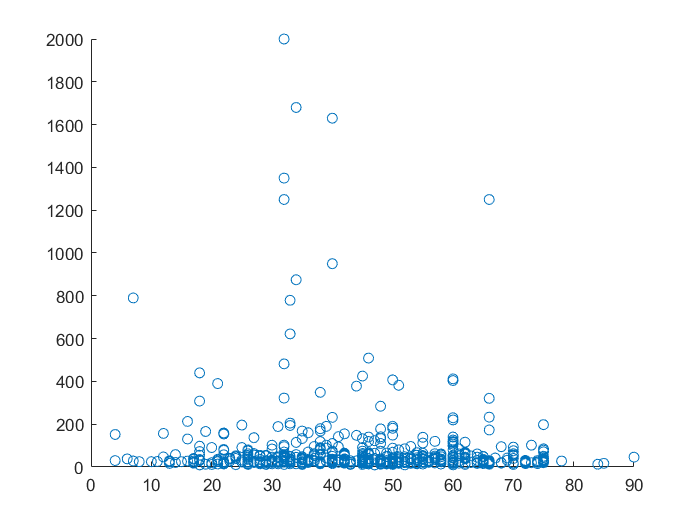


scatter(age,albumin)

Task 6:

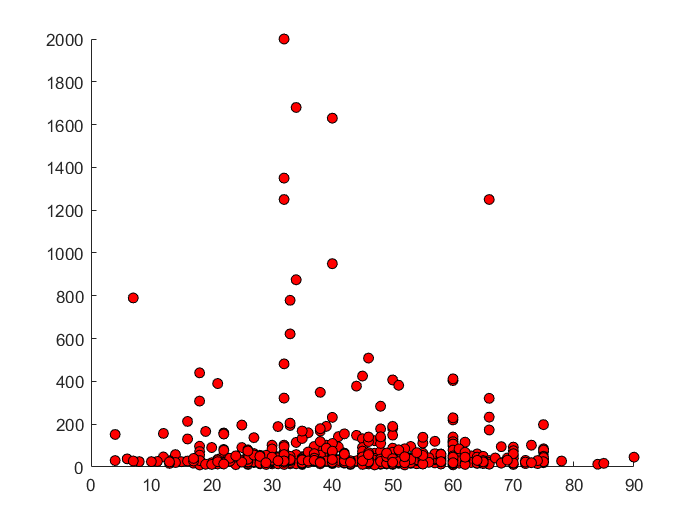

% Using suitable name-value pairs in a new call to scatter(), change the style
% of the plotted points so that they are solid red circles with black edges
% type your solution on the line below:
scatter(age, albumin, 'MarkerEdgeColor','black', 'MarkerFaceColor','red')

Task 7:

% add a new method to Part5_class which will accept the names of two columns
% in the examples table and use them to generate a scatter graph
% type an example call to your new method on the line below:
Part5_class.graphScat(my_m,'age','albumin')